quadripolaire

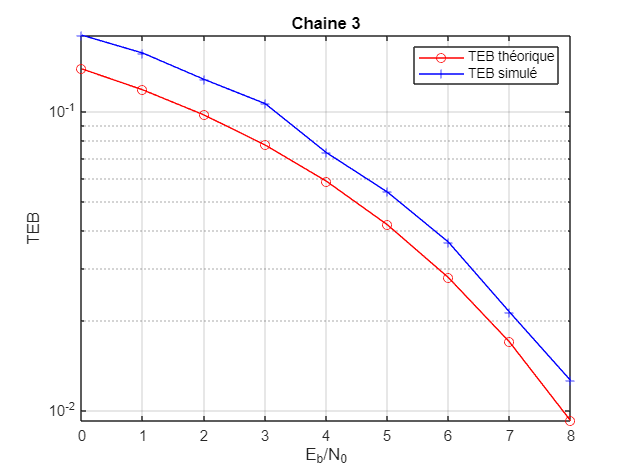

clear all
close all

%PARAMETRES
%Ordre de la modulation
M=4;
%Fréquence d'échantillonnage
Fe=24000;
%Débit binaire
Rb=6000; %en bit/s = 1/Tb
%Facteur de suréchantillonnage
Ns=Fe/Rb;
%Réponse impulsionnelle du filtre de mise en forme
%Réponse impulsionnelle du filtre de mise en forme
h=ones(1,Ns);
%Réponse impulsionnelle du filtre de réception
hr=fliplr(h);
%Valeurs de Eb/N0 à tester
tab_Eb_sur_N0_dB=[0:8];
TEB_simu = zeros(1, length(tab_Eb_sur_N0_dB));
N_bit_block = 2000;



%BOUCLE SUR LES VALEURS DE Eb/N0 --> Chaine 2
for indice_Eb_sur_N0=0:length(tab_Eb_sur_N0_dB)-1
    %Valeur testée
    Eb_sur_N0_dB=tab_Eb_sur_N0_dB(indice_Eb_sur_N0+1);
    Eb_sur_N0_lin = 10^(Eb_sur_N0_dB/10);

    Eb_sur_N0_lin_vect = 10.^(tab_Eb_sur_N0_dB/10);
    %Compteurs (erreurs, nombre de boucles)
    nb_erreurs=0;
    compteur=0;
    
    %BOUCLE SUR LE NOMBRE D'ERREURS (voir précision sur la mesure du TEB)
    while(nb_erreurs<1000)
        
        %MODULATEUR BANDE DE BASE
        %-----------------------------------------------------------------------
        %Information binaire
        bits=randi([0,1],1,N_bit_block);

        % Mapping : 00->-3, 01->-1, 10->1, 11->3
        symboles = (2*bi2de(reshape(bits, 2, length(bits)/2).', 'left-msb') - 3).';
        % On force 'symboles' en vecteur ligne pour éviter les erreurs de kron/filter
        symboles = symboles(:).'; 


        %Suréchantillonnage
        diracs=kron(symboles,[1 zeros(1,Ns-1)]);

        %Filtrage de mise en forme
        signal_emis=filter(h,1,diracs);
        signal_emis = signal_emis(:).'; % Force en vecteur LIGNE (1 x N)

        %CANAL DE PROPAGATION AWGN
        %----------------------------------------------------------------------
        %Puissance du signal
        Pr=mean(abs(signal_emis).^2);
        %Puissance du bruit
       
        Pb = (3/4) * 0.5 * erfc( sqrt( ((4/5) * Eb_sur_N0_lin )) / sqrt(2) ) ;
        Pb_vect = (3/4) * 0.5 * erfc( sqrt( ((4/5) * Eb_sur_N0_lin_vect ))/ sqrt(2) ) ;
        
        
        sigma_n_sq = (Pr * Ns) / (2 * log2(M) * Eb_sur_N0_lin);

        %Génération du bruit
        bruit=sqrt(sigma_n_sq)*randn(1,length(signal_emis));
        %Ajout du bruit
        signal_recu=signal_emis+bruit;

        %DEMODULATEUR BANDE DE BASE
        %---------------------------------------------------------------------
        %Filtrage de réception
        signal_filtre=filter(hr,1,signal_recu);
        %Choix de t0
        t0=Ns;
        %Echantillonnage
        signal_echantillonne=signal_filtre(t0:Ns:end);
        
        %Décisions
        r = signal_echantillonne / Ns;
        
        symboles_decides = zeros(1, length(r));
        symboles_decides(r < -2) = -3;
        symboles_decides(r >= -2 & r < 0) = -1;
        symboles_decides(r >= 0 & r < 2) = 1;
        symboles_decides(r >= 2) = 3;
        
        %Demapping
        dec_decides = (symboles_decides + 3) / 2;
        bits_decides_mat = de2bi(dec_decides, 2, 'left-msb');
        bits_decides = reshape(bits_decides_mat.', 1, []);
        
        %Estimation du TEB pour cette boucle
        nb_erreurs= nb_erreurs + (sum(bits ~=bits_decides));
        compteur=compteur+1;
    end
    TEB_simu_cumul = nb_erreurs/N_bit_block ;
    %TEB SIMULE POUR LA VALEUR TESTEE DE Eb/N0
    TEB_simu(indice_Eb_sur_N0+1)= TEB_simu_cumul / compteur;
end

%TEB THEORIQUE
TEB_th = Pb_vect ;
%TRACES DES TEBs THEORIQUE ET SIMULE
figure
semilogy(tab_Eb_sur_N0_dB,TEB_th,'r-o')
hold on
semilogy(tab_Eb_sur_N0_dB,TEB_simu,'b-+')
xlabel('E_b/N_0')
ylabel('TEB')
legend('TEB théorique','TEB simulé');
title('Chaine 3')
grid